Generates and saves a centered SIM OTF for each orientation

%Setup initial parameters:
nphases = 5;
norders = 5;
norientations = 1;
lattice_period = 1.16; %Lattice period in microns - this is the coarsest period
phase_step = .232; %Phase step in microns
pxl_dim_PSF = [0.11,0.11,0.2*sind(32.4)];  %Voxel dimensions of the PSF in microns - note, stored as [dy,dx,dz]
background=105; %Background to subtract from the images - necessary to remove DC from fourier space

PSF_folder = ['..\data\'];
PSF_file = ['PSF_5phase.tif'];

%Load the PSF data
PSF=double(loadtiff([PSF_folder,PSF_file]));
PSF=PSF-background;
PSF(PSF<0)=0;
[ny_PSF,nx_PSF,nimgs_PSF] = size(PSF);
nz_PSF=nimgs_PSF/(nphases*norientations);
dk_PSF=1./([ny_PSF,nx_PSF,nz_PSF].*pxl_dim_PSF);

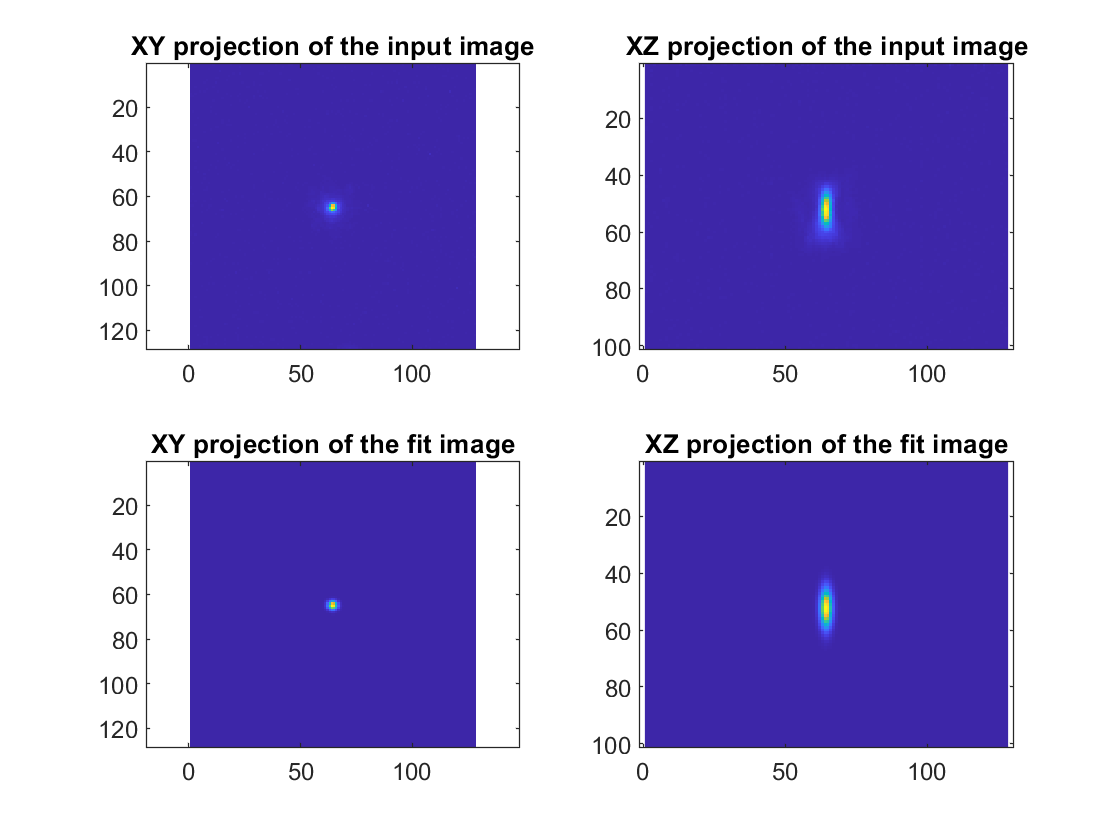

%First - center the bead in the volume to get rid of any phase ramps in the
%OTF. We do this by fitting the widefield PSF which is the sum of all
%phase stepped images per plane
wfPSF=zeros(ny_PSF,nx_PSF,nz_PSF);
tt=1;
for ii=1:nz_PSF
    wfPSF(:,:,ii)=sum(PSF(:,:,tt:tt+(nphases*norientations)-1),3);
    tt=tt+nphases*norientations;
end

%Compute the centroid of the wfPSF by fitting a 3D Gaussian
displayFit=1;
fitParams=Lsq_GaussianFit_3D(wfPSF,displayFit);

%Separate the images for each phase and generate the OTFs
O=zeros(ny_PSF,nx_PSF,nz_PSF,norders,norientations);

for jj=1:norientations
    Dr=zeros(ny_PSF,nx_PSF,nz_PSF,nphases);
    Dr_shift=zeros(ny_PSF,nx_PSF,nz_PSF,nphases);
    Dk=zeros(ny_PSF,nx_PSF,nz_PSF,nphases);
    
    for ii=1:nphases
        Dr(:,:,:,ii)=PSF(:,:,ii+(jj-1)*nphases:nphases*norientations:end);
        %Note - the ceil((nx+1)/2) is there to account for how fftshift and
        %ifftshift deal with even vs. odd sized datasets. Centering the bead at
        %ceil((nx+1)/2)... gives zero phase ramp in the OTF.
        Dr_shift(:,:,:,ii)=fourierShift3D(Dr(:,:,:,ii),[ceil((ny_PSF+1)/2)-fitParams(2),ceil((nx_PSF+1)/2)-fitParams(3),ceil((nz_PSF+1)/2)-fitParams(4)]);
        Dk(:,:,:,ii)=fftshift(ifftn(ifftshift(Dr_shift(:,:,:,ii)))).*1/prod(dk_PSF);
    end
    
    ['Separating information components']
    %Make the forward separation matrix
    [sep_matrix]=make_forward_separation_matrix(nphases,norders,lattice_period,phase_step);
    
    %Make the inverse separation matrix
    inv_sep_matrix=pinv(sep_matrix);
    
    %Separate OTF orders by solving the linear system of equations for each pixel
    for ii=1:nphases
        ii
        for kk=1:nphases
            O(:,:,:,ii,jj)=O(:,:,:,ii,jj)+inv_sep_matrix(ii,kk)*Dk(:,:,:,kk);
        end
    end
end

ans = 'Separating information components'

ii = 1

ii = 2

ii = 3

%Normalize OTF's so that 0th order of each orientation has unit energy
for jj=1:norientations
    OTF0=O(:,:,:,ceil(norders/2),jj);
    energy=sum(OTF0(:).*conj(OTF0(:))*prod(dk_PSF));
    O(:,:,:,:,jj)=O(:,:,:,:,jj)/sqrt(energy);
end

save([PSF_folder,PSF_file(1:end-5),'_OTF_normalized.mat'],'O')

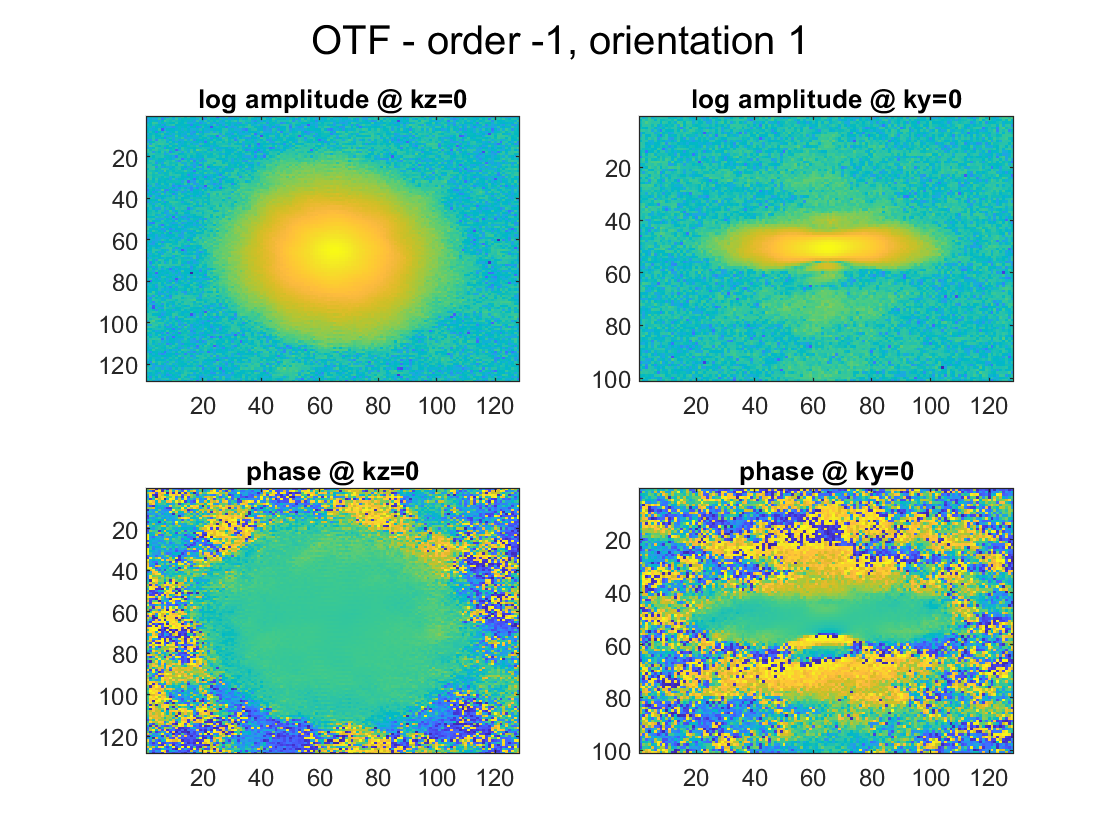

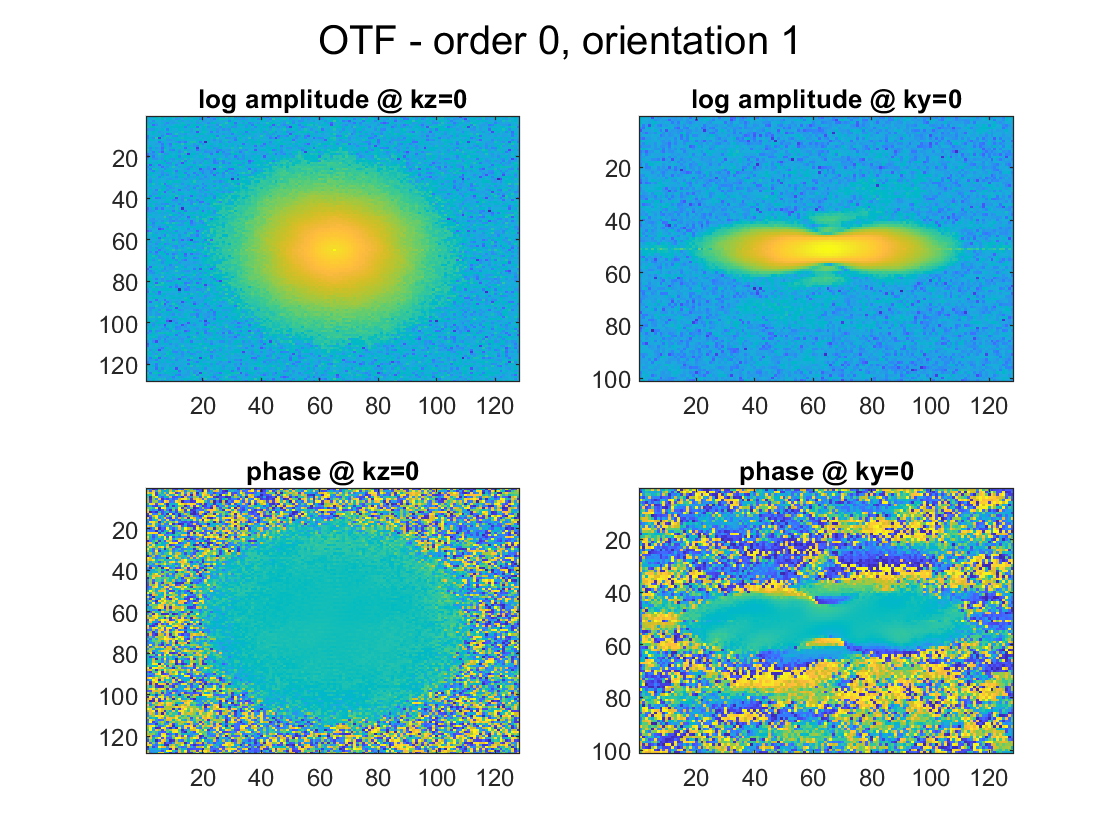

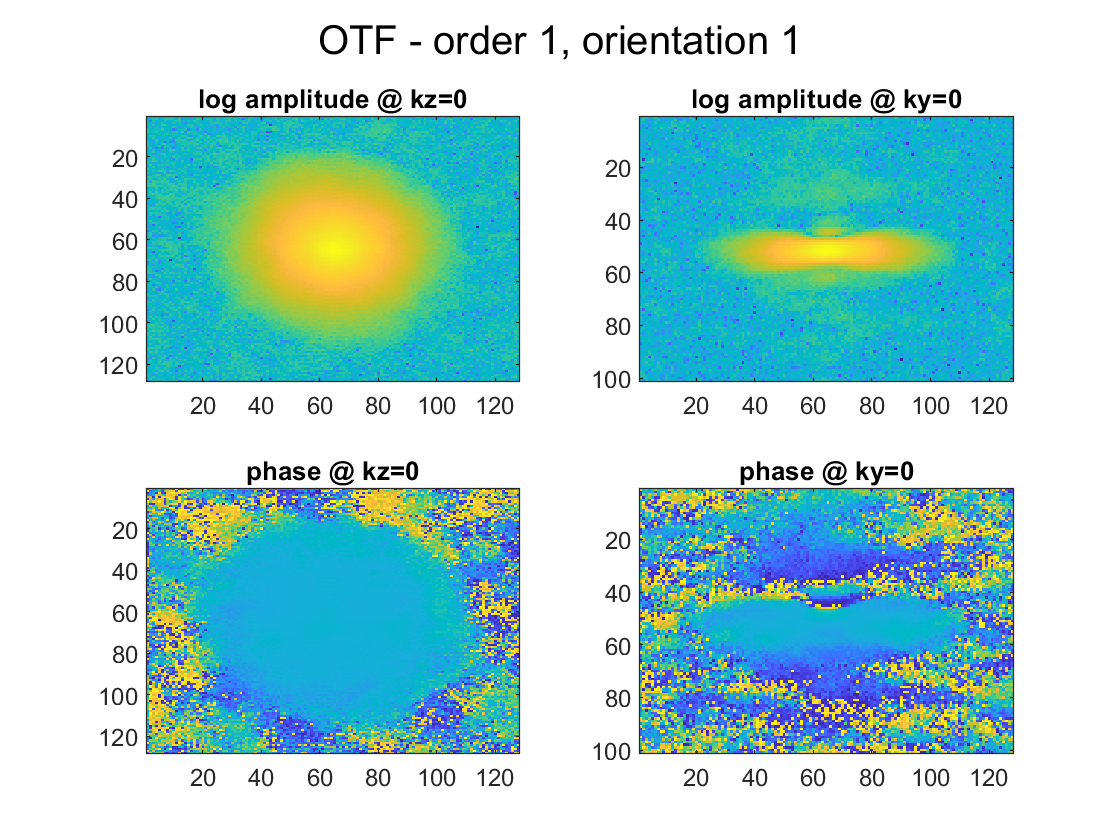

%Display the separated OTF orders
for jj=1:norientations
    for ii=1:norders
        figure
        sgtitle(['OTF - order ',num2str(ii-ceil(norders/2)), ', orientation ',num2str(jj)])
        subplot(2,2,1)
        imagesc(squeeze(log(abs((O(:,:,ceil(nz_PSF/2),ii,jj))))))
        title('log amplitude @ kz=0')
        subplot(2,2,3)
        imagesc(squeeze(angle((O(:,:,ceil(nz_PSF/2),ii,jj)))))
        title('phase @ kz=0')
        subplot(2,2,2)
        imagesc(imrotate(squeeze(log(abs((O(ceil(ny_PSF/2),:,:,ii,jj))))),90))
        title('log amplitude @ ky=0')
        subplot(2,2,4)
        imagesc(imrotate(squeeze(angle((O(ceil(ny_PSF/2),:,:,ii,jj)))),90))
        title('phase @ ky=0')
    end
end